# **An introduction to ISETBIO scene objects**

ISETBIO is structured around a few key objects.  Conceptually, the first two are  the scene (spectral radiance) and the optical image (spectral irradiance at the retina).  The next objects are the cone mosaic, the bipolar layer, and then the retinal ganglion cell layer.

This script illustrates the ISETBIO  scene and describes how to program with the ISETBIO style. Using ISETBIO objects properly will make your code and analysis are much easier to understand. 

For the scene and oi representations there are six fundamental operations:

   Create, set parameters, get parameters, compute, plot and a window function.

## Historical note

The scene and optical image (oi) were implemented before Matlab provided object-oriented programming with classes and methods. But the principles of the struct implementaiton are the same. Thus, the scene and oi are represented as Matlab structs along and a set of object-oriented functions that interact with these structs.

The newer objects (such as cone mosaics and bipolar cells and retinal ganglion cells) are implemented using Matlab's classes and methods. Conceptually, the programming is the same, based on creating, setting, getting, computing, plotting and a window interface.

## 3D scenes

The scene describes the spectral radiance.  For the present tutorial we explain a planar spectral radiance image, such as the image on a display surface. We have implemented more advanced methods based on 3D scenes created using quantitative computer graphics.  These methods are integrated with ISETBIO, but they require installing the pbrt2ISET toolbox (described on the Home wiki page)

Notes:

  Use t_<tab> at the Matlab command line to see a list of all ISETBIO tutorials.

**See also: **t_oiIntroduction

**Copyright ImagEval Consultants, LLC, 2011.**

## Initializing ISETBio

ISETBIO stores a small database of scenes and optical images.  This command clears that database. The variables themselves are not cleaned. You can use the "clear" command to remove these variables.

ieInit;

## Create a scene and explore some of its features

The create function initiates the scene struct. There are many different pre-defined test scenes including color targets, patterns, charts, and images.  Here is a scene of a color test chart.

scene = sceneCreate('macbeth d65');

You can see the scene structure by typing

scene

scene = struct with fields:
             type: 'scene'
             data: [1×1 struct]
         spectrum: [1×1 struct]
             name: 'Macbeth (D65)'
         distance: 1.2000
    magnification: 1
       illuminant: [1×1 struct]
         wAngular: 10


To see the range of pre-defined scenes, type

doc sceneCreate

We add the scene to the database and then invoke a window (GUI) to help you interact with the scene.  (You can add multiple scenes to the database and click through them from the GUI).

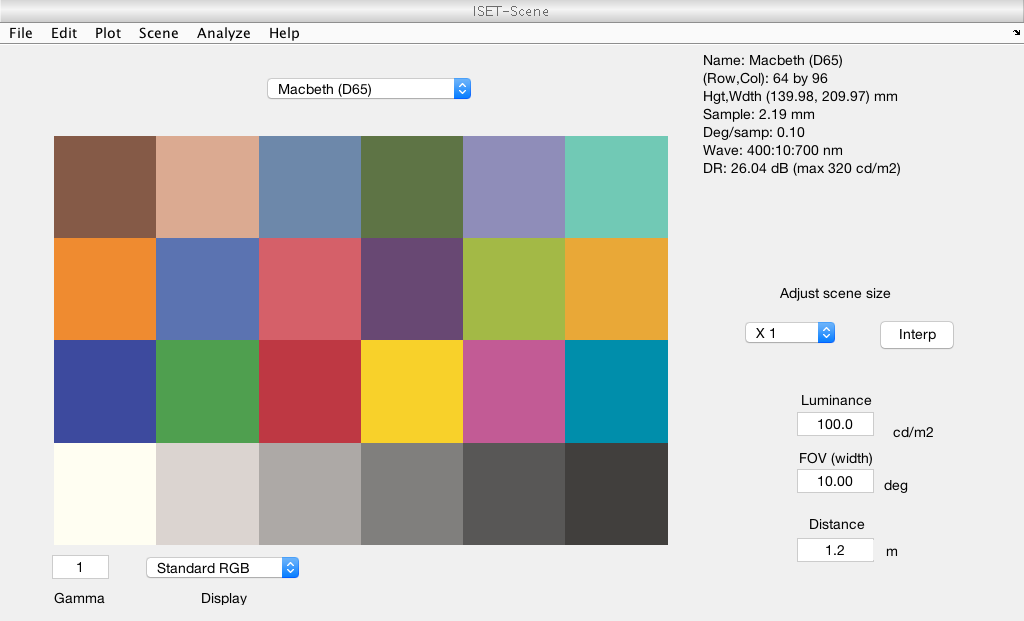

ieAddObject(scene);
sceneWindow;

You can scale the window size and adjust the font size as well 

  (Edit | Change Font Size)

There are many other options in the pull down menus for cropping, transposing, and measuring scene properties.

## Interact with an object parameters using the get and set functions

% Each object has a name and a type.  To see its name, you use sceneGet()
name = sceneGet(scene,'name')

name = 'Macbeth (D65)'


% You can use sceneGet to read many scene parameters  For example a scene
% has a horizontal field of view
hFOV = sceneGet(scene,'hfov')

hFOV = 10


% Use sceneSet to change a scene property
scene = sceneSet(scene,'hfov',0.5);  % In degrees of visual angle

% Confirm that the set worked
hFOV = sceneGet(scene,'hfov')

hFOV = 0.5000

## Philosophical interlude - programming issues

There are always more parameters to "get" than are to "set". This is because there are dependencies among any object parameters. For example, if you know the image distance and horizontal field of view, you can compute the spatial sample spacing.

In designing the objects, we had to select an approach: Do we allow the user to set anything and then update the other parameters for consistency, or do we only allow the user to set specific parameters and through this limitation enforce consistency. 

ISETBIO is designed to have a relatively small number of parameters to set and a large number of parameters to get.

## More about gets and sets

The objects in ISETBIO are structs, and their values can be set directly - but please don't. If you are tempted to set the objects directly, go have a cup of tea. When you return, use sceneSet.

% You can see the scene parameters you can set by typing
%    help sceneSet
%    help sceneGet
%
% For a nicer formatting, use the Matlab doc command
%   doc sceneGet
%   doc sceneSet

## Explore the relationship between parameters

To see an example of the dependence, consider the effect of scene distance, which we can get, on scene sample spacing.

dist    = sceneGet(scene,'distance','mm');
spacing = sceneGet(scene,'sample spacing','mm');
dist

dist = 1200


% If we move the scene closer, and we maintain the same number of row and
% column samples, the spacing changes.
scene = sceneSet(scene,'distance',0.6);
sceneGet(scene,'sample spacing','mm');

## You can change the distance and horizontal field of view (hFOV)

The geometric relationship between viewing distance, FOV, and number of samples means that these adjustments change the the distance between the spatial samples of the image. 

scene = sceneSet(scene,'hfov',hFOV/2);
sceneGet(scene,'sample spacing','mm')

ans =     0.0273    0.0273


## Scene illuminant

Many scene properties can be plotted using the scenePlot function For example, ISETBIO scenes specify a uniform illuminant by default. You can plot the illuminant in energy units by this command.  This plots shows the  illuminant.

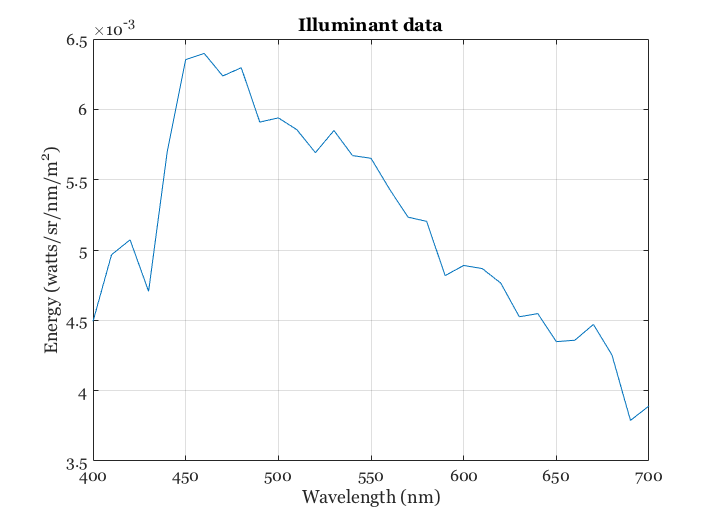

% We start out assuming the display white point is the illuminant
scenePlot(scene,'illuminant energy');


% The scenePlot command is equivalent to
%  wave = sceneGet(scene,'wave');
%  illuminant  = sceneGet(scene,'illuminant energy');
%  vcNewGraphWin; plot(wave,illuminant); grid on
%  xlabel('wave (nm)'); ylabel('Energy (watts/sr/nm/m^2)')

## Specifying units

In many cases, we the user can specify the units of a value through the function.  For example, we asked for the sample spacing we used millimeters (mm). We could have specified microns, or meters.

sceneGet(scene,'sample spacing','um')

ans =    27.2708   27.2708


sceneGet(scene,'sample spacing','m')

ans =    1.0e-04 *

    0.2727    0.2727


## Reading a scene from a file

ISETBIO can read multispectral scenes, but these are large files.  Consequently, the default distribution only includes one example. We have another 100 or so that are available on the related web site (see RemoteDataToolbox).

fname = fullfile(isetbioDataPath,'images','multispectral','stuffedAnimals_tungsten-hdrs.mat');
scene = sceneFromFile(fname,'multispectral');

Reading multispectral data with mcCOEF.
Saved using svd method


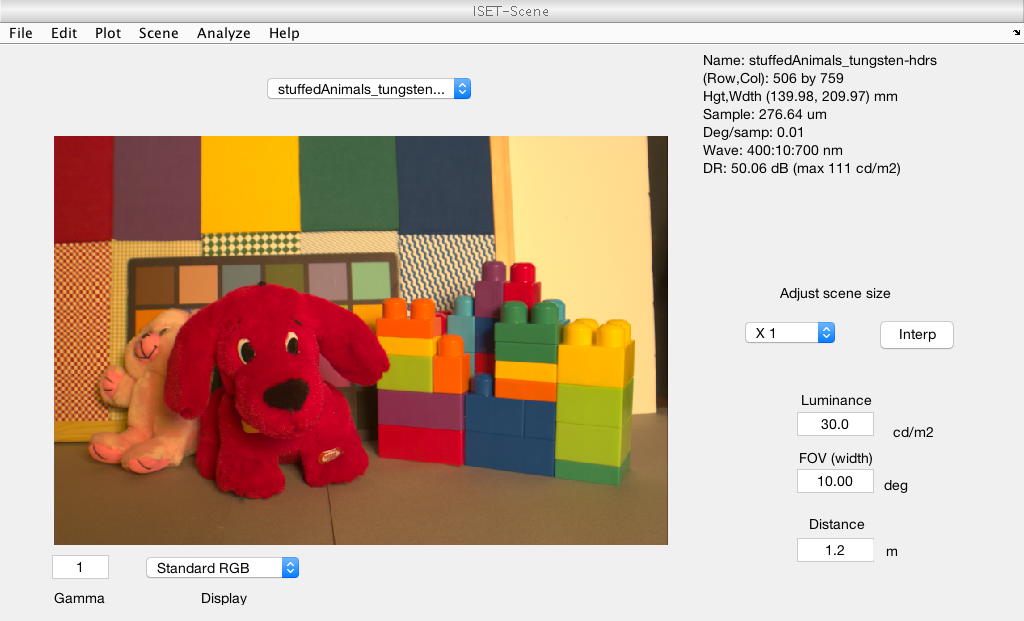

ieAddObject(scene); sceneWindow;

## Creating a scene from  RGB data

If the wavelength data are not critical for your analysis, we have a means of converting RGB images into a scene spectral radiance.  We treat the RGB file as if it is shown on a display, and then we calculate the spectral radiance of the image from the display. When we convert an RGB file to a scene, we use the display white point is the illuminant. 

fname = 'ma_blkbkjackal_412.jpg';
scene = sceneFromFile(fname,'rgb',100,'LCD-Apple.mat');

[vcReadImage] Assuming an 8bit image and a 10 bit LUT


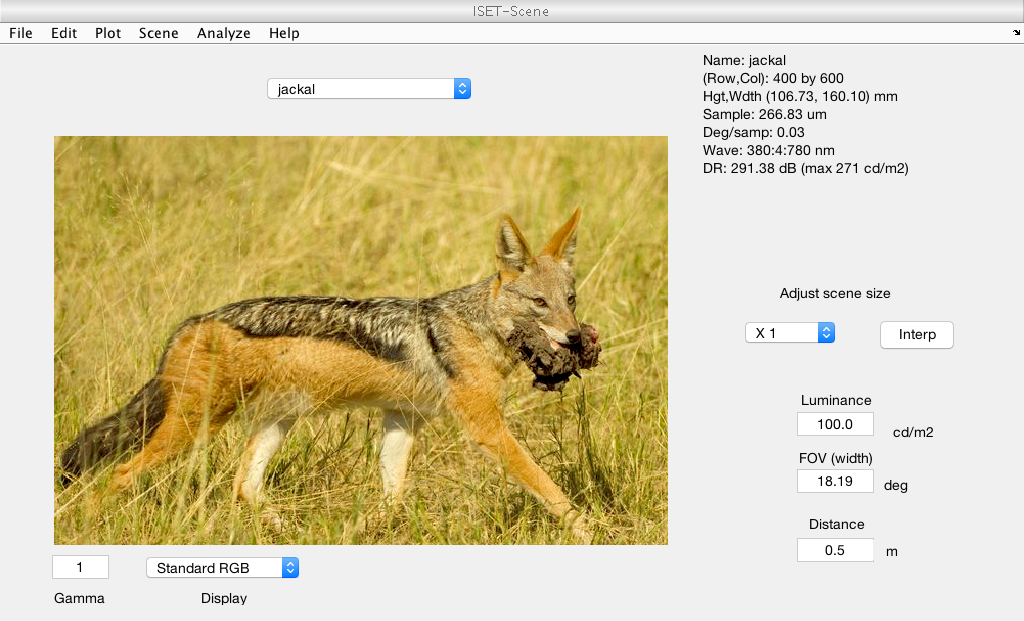

scene = sceneSet(scene,'name','jackal');
ieAddObject(scene); sceneWindow;

## Changing the illuminant spectral power distribution

You can also change the scene illuminant.  This code creates a blackbody illuminant and reilluminates the scene.  Try using the drop down menu to flip back and forth between the scenes so you can more easily see the consequences of changing the illuminant.

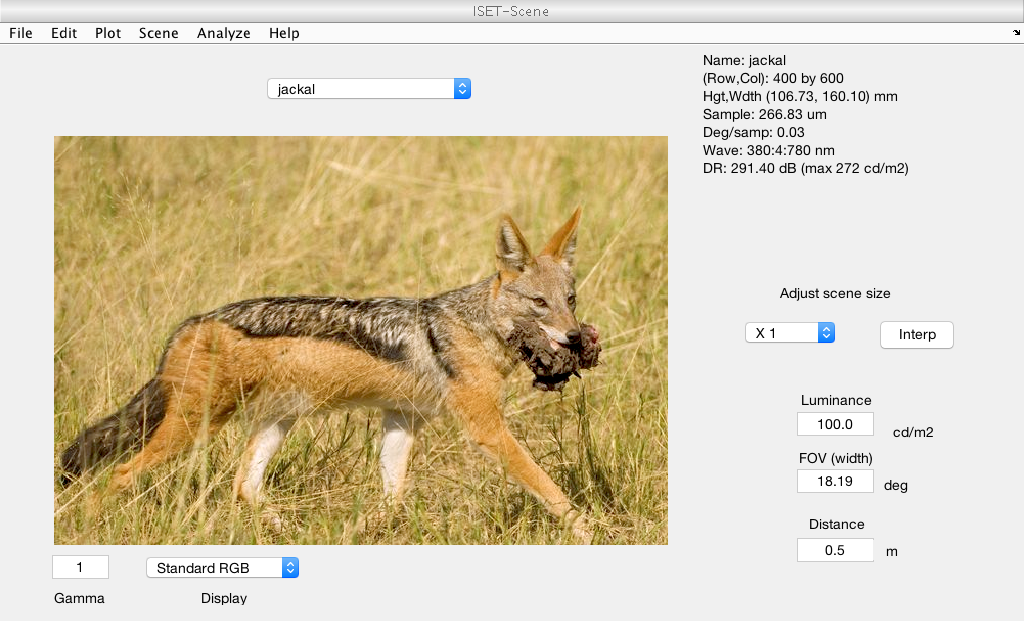

bb = blackbody(sceneGet(scene,'wave'),8000,'energy');
scene = sceneAdjustIlluminant(scene,bb);
ieAddObject(scene); sceneWindow;

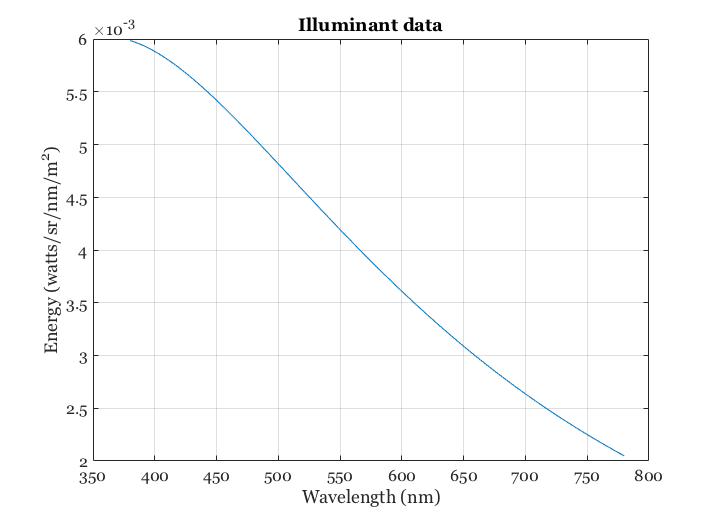

scenePlot(scene,'illuminant energy');